## 1.  Use `bp3.m` to train an 8-2-8 autoencoder.  Use eye(8) for the set of stimulus patterns (`p8.smat`).

rs = rng;
p8.smat = eye(8);
net0 = initnet3(8,2,8,2,2,rs);

a. For the targets, use `p8.tmat = eye(8)`

p8.tmat = eye(8);
neta = bp3(net0,p8,10000,1,0,rs);
acta = forw3(neta,p8)

acta = struct with fields:
    stim: [8×8 double]
     hid: [8×2 double]
     out: [8×8 double]

b. For `p8.tmat` field, try this: 

`i8 = eye(8);` 

`p8.tmat = i8 + i8([2 3 4 5 6 7 8 1] , :) +  i8([8 1 2 3 4 5 6 7] , :) ;`

i8 = eye(8) ;
p8.tmat = i8 + i8([2 3 4 5 6 7 8 1],:) + i8([8 1 2 3 4 5 6 7],:);
p8.tmat

ans =      1     1     0     0     0     0     0     1
     1     1     1     0     0     0     0     0
     0     1     1     1     0     0     0     0
     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     0     0
     0     0     0     0     1     1     1     0
     0     0     0     0     0     1     1     1
     1     0     0     0     0     0     1     1


netb = bp3(net0,p8,10000,1,0,rs);
actb = forw3(netb,p8)

actb = struct with fields:
    stim: [8×8 double]
     hid: [8×2 double]
     out: [8×8 double]

After checking the outputs for accuracy, examine the hidden unit representations.

acta.out

ans =        0.7838      0.14658   5.3932e-22   2.4789e-18   0.00076799   9.2751e-16   5.4676e-07    5.014e-20
     0.049224      0.70029    2.865e-20   5.3635e-06   1.5094e-16    0.0054259   2.9759e-19   4.0409e-22
   1.4023e-22     1.32e-20      0.84334   0.00050663   2.9356e-19   2.4964e-06   1.1264e-15     0.077584
   2.4925e-19   1.7882e-16    0.0031379      0.63235   9.0512e-23      0.10208   3.2251e-20   2.9954e-06
      0.11675   0.00055807    1.526e-20   1.3005e-22      0.94384    9.647e-21     0.035156   3.5017e-17
    2.438e-05    0.0091145   5.1178e-17       0.0415    1.155e-20      0.91867   2.1823e-22   5.4649e-20
    1.998e-16   1.6677e-18   6.1757e-06   6.4345e-21     0.089811   7.3987e-23      0.87857     0.012384
   3.0716e-20   4.8055e-22     0.033718   1.1357e-19    0.0038656   1.5722e-22      0.80342      0.97447


actb.out

ans =             1      0.99961      0.80476   1.5963e-08   1.2646e-12   6.9689e-12    0.0010547      0.19996
            1      0.99961      0.80478   1.5966e-08   1.2648e-12   6.9691e-12    0.0010545      0.19994
    0.0019176       0.8952            1      0.99985      0.10509   3.4127e-09   9.7202e-15   1.0331e-12
    0.0019065      0.89508            1      0.99985      0.10563   3.4175e-09   9.6638e-15   1.0269e-12
   1.8235e-13   8.2554e-11    0.0011482      0.99787            1      0.99997    0.0019954   7.5545e-09
   2.1275e-08   7.8001e-10   4.2191e-07    0.0013115      0.99924       0.9997      0.99825    0.0023015
    0.0095574   1.1549e-08   8.7966e-11   1.0678e-09    0.0030806      0.99462            1      0.99956
      0.99013   0.00029049   1.1948e-06   2.9932e-09   6.9573e-07    0.0011465      0.99993      0.98535


## 2.  Use bp3.m to train an 8-3-8 autoencoder.  Examine the hidden unit representations using scatter3.

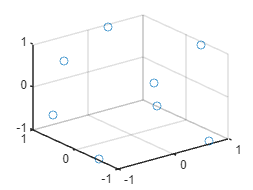

q2net0 = initnet3(8,3,8,2,2,rs);
p8.tmat = eye(8);
q2netfinal = bp3(q2net0,p8,10000,1,0,rs);
q2actfinal = forw3(q2netfinal,p8);

scatter3(q2actfinal.hid(:,1),q2actfinal.hid(:,2),q2actfinal.hid(:,3))

## 3.  Use bp3.m to train a 12-3-12 autoencoder.  Examine the hidden unit representations using scatter3.

p12.smat = eye(12);
p12.tmat = eye(12);
q3net0 = initnet3(12,3,12,2,2,rs);
q3netfinal = bp3(q3net0,p12,10000,1,0,rs);
q3actfinal = forw3(q3netfinal,p12)

q3actfinal = struct with fields:
    stim: [12×12 double]
     hid: [12×3 double]
     out: [12×12 double]

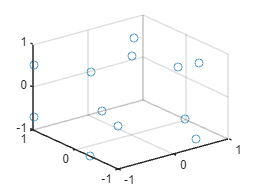


scatter3(q3actfinal.hid(:,1),q3actfinal.hid(:,2),q3actfinal.hid(:,3))